Load the Apple Watch dataset into the variable "data" using the Turbo drive path

temp = load('Z:\Projects\Toyota\Data\Processed\BigIdeasLab_HRSmartwatch\hrdata.mat');
data = temp.hrdata;

From what we have learned from the BigIdeasLab dataset so far, we know that Apple Watch HR is often different from ECG HR. 

- Apple Watch HR differs more from ECG HR during "Breathe" and "Activity", while Apple Watch HR seems to more closely match ECG HR during "Type". 

- When Apple Watch HR is around 80 to 100, ECG HR is more likely to be accurate. 

We can conclude that there are two independent variables or "features" that may be able to predict the difference between Apple Watch HR and ECG HR.

TASK 1: Name the two variables:  Activity Type and Apple Watch HR

If we can predict the HR difference, we can use the difference to adjust the Apple Watch HR to be more accurate. 

This will allow you to reduce the mean absolute error (MAE) of any patients who wear the Apple Watch!

Most importantly, for any new patient who wears the Apple Watch and doesn't wear the ECG monitor, we can still predict what their true ECG heart rate might be by using the Activity and Apple Watch HR variables.

Now let's separate our dataset into a training and testing set.

[https://machinelearningmastery.com/data-leakage-machine-learning/](https://machinelearningmastery.com/data-leakage-machine-learning/)

% get the matched datapoints from the interpolated dataset
matched = data((~isnan(data.ECG) & ~isnan(data.AppleWatch)), :);
MDE = mean(matched.ECG - matched.AppleWatch);
MAE = mean(abs(matched.ECG - matched.AppleWatch));
disp(MDE)  % mean directional error

    0.3186



disp(MAE) % mean absolute error

    5.4191



% check how many unique patients exist in the dataset
pt_id = unique(matched.ID);
disp(['There are a total of ' num2str(length(pt_id)) ' unique patients in the dataset'])

There are a total of 53 unique patients in the dataset


We will create a training and testing dataset by splitting the data by patient. Generally we use 80% of data in training and 20% in testing. 

So our training set will consist of 42 training patients and 11 testing patients.

TASK 2: Why do machine learning experiments have to split a dataset into training and testing? 

Why do we have to split up the data by patient?

% shuffle patient list
shuffle_pt = pt_id(randperm(length(pt_id)));

% get an array of patient ids for both the 42 training and 11 test patients
train_pt = shuffle_pt(1:42);
test_pt = shuffle_pt(43:end);

disp(['Number of training patients: ' num2str(length(train_pt))])

Number of training patients: 42


disp(['Number of testing patients: ' num2str(length(test_pt))])

Number of testing patients: 11


Let's do some visualization of the training data before we start.

% get training and test data rows
train_data = matched(ismember(matched.ID, train_pt), [1,2,8,10]);
test_data = matched(ismember(matched.ID, test_pt), [1,2,8,10]);
train_data.Error = train_data.ECG - train_data.AppleWatch;
test_data.Error = test_data.ECG - test_data.AppleWatch;

What is the relationship between Apple Watch, Activity type, and Error in the training data?

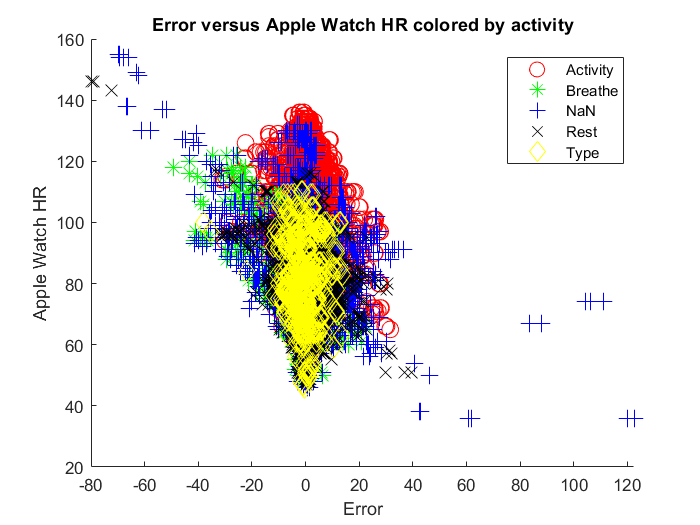

figure; hold on;
gscatter(train_data.Error, train_data.AppleWatch, train_data.Activity, 'rgbky', 'o*+xd', [10 10 10 10 10], 'on')
title('Error versus Apple Watch HR colored by activity')
xlabel('Error')
ylabel('Apple Watch HR')
legend('Location', 'best')
xlim('tight')

A bar graph can better visualize the average error of each activity type.

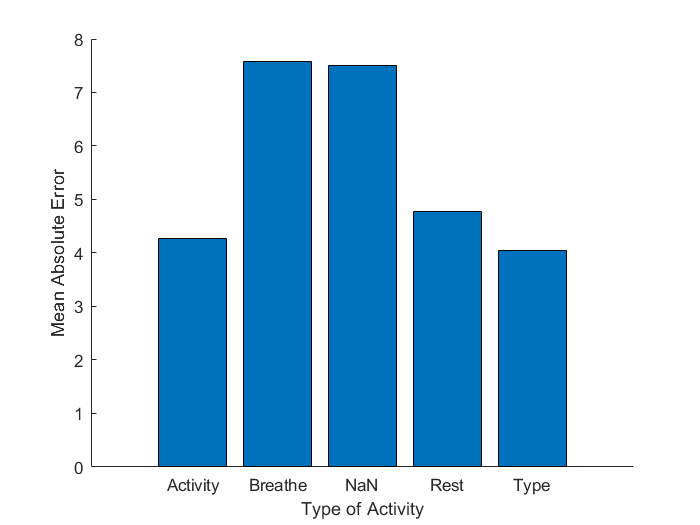

% get average error for each activity type
unique_activity = unique(train_data.Activity);
activity_error = zeros(length(unique_activity), 1);
for ai = 1:length(unique_activity)
    activity_name = unique_activity(ai);
    activity_idx = train_data.Activity == activity_name;
    avg_error = mean(abs(train_data.Error(activity_idx)));
    activity_error(ai) = avg_error;
end
figure; hold on;
bar(activity_error);
set(gca, 'XTick',[1 2 3 4 5])
set(gca, 'xticklabels', cellstr(unique_activity));
xlabel('Type of Activity')
ylabel('Mean Absolute Error')

TASK 3: Why does NaN have the highest average error? Should we include this activity type in our analysis?

% remove NaN from the dataset
train_data_clean = train_data(train_data.Activity ~= 'NaN', :);
test_data_clean = test_data(test_data.Activity ~= 'NaN', :)

test_data_clean = 2032×5 table
     ECG      AppleWatch      ID      Activity     Error 
    ______    __________    ______    ________    _______

    71.719        91        19-004      Rest      -19.281
    77.672        77        19-004      Rest        0.672
    70.287        76        19-004      Rest       -5.713
     70.31        76        19-004      Rest        -5.69
    68.626        74        19-004      Rest       -5.374
    70.169        74        19-004      Rest       -3.831
     67.76        72        19-004      Rest        -4.24
    70.565        70        19-004      Rest        0.565
    78.166        71        19-004      Rest        7.166
    78.166        71        19-004      Rest        7.166
    62.118        73        19-004      Rest      -10.882
    72.803        75        19-004      Rest

Now plot the new scatterplot of cleaned training data.

% your code here

Now we train a machine learning model to predict the difference between Apple Watch HR and ECG HR.

In machine learning, when we try to predict a quantitative value (number) associated with a data sample, we use **regression** models.

When trying to predict the distinct class of a data sample, we use **classification** models.

TASK 4: What type of machine learning model should we use here?

Linear regression can find a line of best fit for our data. This model is the most basic regression model, let's see how well it fits our training data.

[https://www.mathworks.com/help/matlab/data_analysis/linear-regression.html](https://www.mathworks.com/help/matlab/data_analysis/linear-regression.html)

% before we can fit the model, we need to take care of the categorical
% variable!
train_data_clean.Activity

ans = 7412×1 categorical array
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 
     Rest 


% This variable can't just go into the linear regression model.
% Instead we need to one hot encode (also called dummy code) the variable
onehotencode(train_data_clean.Activity,2)

ans =      0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0


Here you can see that instead of using the string "Rest" which a numerical model can't make sense of,

we expand the variable into 5 columns, one column for each type of activity.

% get the training variables (X) and training target (Y)
train_X = [train_data_clean.AppleWatch onehotencode(train_data_clean.Activity,2)];
train_Y = train_data_clean.Error;

test_X = [test_data_clean.AppleWatch onehotencode(test_data_clean.Activity,2)];
test_Y = test_data_clean.Error;

Train a linear regression model.

[https://www.mathworks.com/help/matlab/data_analysis/linear-regression.html](https://www.mathworks.com/help/matlab/data_analysis/linear-regression.html)

linearModel = fitlm(...
    train_X, ...
    train_Y, ...
    'linear', ...
    'RobustOpts', 'off');


% calculate RMSE metric for training data
predict_Y = predict(linearModel, train_X);
diffs = train_Y - predict_Y;
rmse = sqrt(mean(diffs.^2))

rmse = 6.9181

Train an ensemble of tree models (random forest).

[https://en.wikipedia.org/wiki/Random_forest](https://en.wikipedia.org/wiki/Random_forest)

template = templateTree(...
    'MinLeafSize', 1, ...
    'NumVariablesToSample', 5);
regressionEnsemble = fitrensemble(...
    train_X, ...
    train_Y, ...
    'Method', 'Bag', ...
    'NumLearningCycles', 10, ...
    'Learners', template);

% calculate RMSE metric for training data
predict_Y = predict(regressionEnsemble, train_X);
diffs = train_Y - predict_Y;
rmse = sqrt(mean(diffs.^2))

rmse = 6.3592

Train a 1-layer neural network model with 10 neurons.

regressionNeuralNetwork = fitrnet(...
    train_X, ...
    train_Y, ...
    'LayerSizes', 10, ...
    'Activations', 'relu', ...
    'Lambda', 0, ...
    'IterationLimit', 1000, ...
    'Standardize', true);

% calculate RMSE metric for training data
predict_Y = predict(regressionNeuralNetwork, train_X);
diffs = train_Y - predict_Y;
rmse = sqrt(mean(diffs.^2))

rmse = 6.5389

Let's test the models on the test set.

% linear regression
predict_Y = predict(linearModel, test_X);
diffs = test_Y - predict_Y;
rmse = sqrt(mean(diffs.^2));
disp(['Linear regression RMSE: ' num2str(rmse)])

Linear regression RMSE: 9.9001


% random forest
predict_Y = predict(regressionEnsemble, test_X);
diffs = test_Y - predict_Y;
rmse = sqrt(mean(diffs.^2));
disp(['Random Forest RMSE: ' num2str(rmse)])

Random Forest RMSE: 11.271


% neural network
predict_Y = predict(regressionNeuralNetwork, test_X);
diffs = test_Y - predict_Y;
rmse = sqrt(mean(diffs.^2));
disp(['Neural Network RMSE: ' num2str(rmse)])

Neural Network RMSE: 9.945


TASK 5: What model performed the best on the training set? Was it also the best model on the test set?

You can try out different models by using the regressionLearner app in Matlab. This can also visualize the residuals of the model predictions.

regressionLearner

Now let's use our best model to try to improve the Apple Watch HR compared to ECG HR.

We will only look at the test set.

MDE = mean(test_data_clean.ECG - test_data_clean.AppleWatch);
MAE = mean(abs(test_data_clean.ECG - test_data_clean.AppleWatch));

MDE before model adjustment: 0.94471


disp(['MDE before model adjustment: ' num2str(MDE)])  % mean directional error

MAE before model adjustment: 4.9713


disp(['MAE before model adjustment: ' num2str(MAE)]) % mean absolute error

Adjust Apple Watch HR values according to best model predictions.

predict_Y = predict(linearModel, test_X); % use linear regression
new_AW = test_data_clean.AppleWatch + predict_Y;
MDE = mean(test_data_clean.ECG - new_AW);
MAE = mean(abs(test_data_clean.ECG - new_AW));
disp(['MDE before model adjustment: ' num2str(MDE)])  % mean directional error

MDE before model adjustment: 0.47258


disp(['MAE before model adjustment: ' num2str(MAE)]) % mean absolute error

MAE before model adjustment: 4.9632


Let's plot out the adjustments that the model makes to the Apple Watch HR.

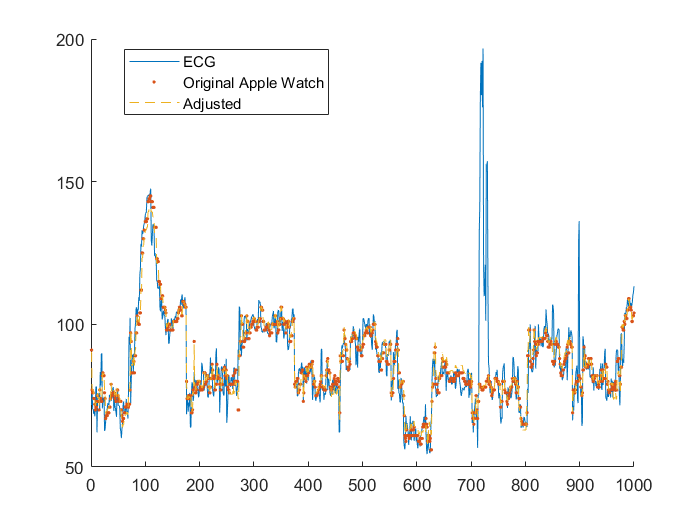

figure; hold on;
plot_idx = [1:1000];  % plot first 250 values
plot_data = test_data_clean(plot_idx, :);
plot_new_AW = new_AW(plot_idx, :);

plot([1:length(plot_data.ECG)], plot_data.ECG)
plot([1:length(plot_data.AppleWatch)], plot_data.AppleWatch, '.')
plot([1:length(plot_data.AppleWatch)], plot_new_AW, '--')
legend('ECG', 'Original Apple Watch', 'Adjusted', 'Location', 'best')

**TASK 6: Conclusions**

We see that using activity type to try to adjust Apple Watch HR towards the true ECG HR can be somewhat effective.

From what we saw last week, Apple Watch tended to overpredict HR when true ECG HR was low, and underpredict HR when ECG HR was high.

Certain activity types such as breathing had higher error compared to activities like typing.

Our machine learning model can nudge Apple Watch HR a bit closer to ECG HR using this information.

Although mean absolute error did not decrease by much, we managed to halve the mean directional error (MDE) in the test set.

If we had more detailed activity data (such as accelerometer data from the Apple Watch), predictions could be more accurate.